% 1: path
filename = 'Courts_data_2024.xlsx';

data = readtable(filename);


colsToRemove = {'Var8', 'Var15', 'Var17', 'Var21'};
data(:, ismember(data.Properties.VariableNames, colsToRemove)) = [];


oldNames = {'Judges', 'Clerks', 'Courtclerks', 'ProbationOfficers', 'Assistants', 'OtherWorkers', ...
            'Judges_1', 'Clerks_1', 'Courtclerks_1', 'ProbationOfficers_1', 'Assistants_1', 'OtherWorkers_1', ...
            'Criminal', 'Civil', 'Family', ...
            'Criminal_1', 'Civil_1', 'Family_1'};

newNames = {'Judges_E', 'Clerks_E', 'Courtclerks_E', 'Probation_officers_E', 'Assistants_E', 'Other_workers_E', ...
            'Judges_S', 'Clerks_S', 'Courtclerks_S', 'Probation_officers_S', 'Assistants_S', 'Other_workers_S', ...
            'Criminal_S', 'Civil_S', 'Family_S', ...
            'Criminal_P', 'Civil_P', 'Family_P'};

% change to columns
for i = 1:length(oldNames)
    idx = find(strcmp(data.Properties.VariableNames, oldNames{i}));
    if ~isempty(idx)
        data.Properties.VariableNames{idx} = newNames{i};
    end
end

format long g
%getting rid of units/index
data = data(:,2:end)

data = 84×19 table
    Judges_E    Clerks_E    Courtclerks_E    Probation_officers_E    Assistants_E    Other_workers_E        Judges_S            Clerks_S         Courtclerks_S      Probation_officers_S      Assistants_S      Other_workers_S     MarketValue    Criminal_S    Civil_S    Family_S    Criminal_P    Civil_P    Family_P
    ________    ________    _____________    ____________________    ____________    _______________    ________________    ________________    ________________    ___________________

disp(data)

    Judges_E    Clerks_E    Courtclerks_E    Probation_officers_E    Assistants_E    Other_workers_E        Judges_S            Clerks_S         Courtclerks_S      Probation_officers_S      Assistants_S      Other_workers_S     MarketValue    Criminal_S    Civil_S    Family_S    Criminal_P    Civil_P    Family_P
    ________    ________    _____________    ____________________    ____________    _______________    ________________    ________________    ________________    ____________________    

QUESTION 1

To evaluate the efficiency of district courts, it is essential to distinguish between **inputs** (resources consumed) and **outputs** (results achieved) in their operations.**Inputs (Resources Utilized)**

- **Number of employees** categorized into six groups:

- Judges

- Clerks

- Court clerks

- Probation officers

- Assistants

- Other workers

- **Average salary per employee category**, reflecting labor costs which are generally fixed but may vary slightly due to experience differences within categories.

- **Value of assets** (both tangible and intangible), representing the physical and non-physical resources available to the court.

These inputs collectively represent the human, financial, and material resources consumed by each court to perform its functions.**Outputs (Results Achieved)**

- **Number of solved cases** during 2024, categorized by case type:

- Criminal cases

- Civil cases

- Family cases

- Number of pending cases at the end of 2024, indicating the backlog and the court’s ability to manage ongoing workloads.

These outputs reflect the court’s productivity and effectiveness in resolving cases and managing caseloads.

MERGED APPROACH


% excluding 3 columns of pending cases
sub_data = data(:,1:16);

% Oblicz sum columns 14, 15, 16 all cases resovled
Sum_cases_resolved = sum(sub_data(:, 14:16), 2);

% connect columns 1-7 (z oryginalnego sub_data) new column Sum_cases_resolved
final_data = [sub_data(:, 1:13), Sum_cases_resolved]

final_data = 84×14 table
    Judges_E    Clerks_E    Courtclerks_E    Probation_officers_E    Assistants_E    Other_workers_E        Judges_S            Clerks_S         Courtclerks_S      Probation_officers_S      Assistants_S      Other_workers_S     MarketValue     sum  
    ________    ________    _____________    ____________________    ____________    _______________    ________________    ________________    ________________    ____________________    ________________    ________________    ___________    ______

%prices are avg salares of employees
prices = final_data(:,[10,11,12]);
prices=table2array(prices);
data_inout = final_data(:,[1,2,3,4,5,6,7,8,9,13,14]);
data_inout = table2array(data_inout);
data_inout(:, 4:6) = data_inout(:, 4:6) .* prices

data_inout =                         36                         7                     103.5           216158.69041463          125097.895467961          34659.5738905539          16611.0548075725          13425.9591139951          7152.02649528279                 926459.06                     42238
                        40                        54                    235.25          264521.673764866          138912.358604285          79723.0789540755          15810.3434132344          12778.7805592899          6807.27360790024                  53190.12                    324959
                        46                         6                       127          435698.887743558          137283.178220445          76071.2471087129          15624.9178570823            12628.90952675          6727.43710709608                4239265.82                     46652
                        58                         7                     180.1          312620.930559109           238313.4175

% 3[judges, clerks, courtclerks] employees number; 3 [probation, assistants,other] salary*number of employees;
% 3[judges, clerks, courtclerks] fixed salaries; 1 asset value; 1 output 
[n,m]=size(data_inout);
inputs=7;
outputs=1;
    

%% Merge approach
X=data_inout(:,[1,2,3,4,5,6,10]); 
Y=data_inout(:,m);
cost_efficiency_T=nan(n,1);
observed_cost = sum(data_inout(:,4:6), 2) + ...
                sum(data_inout(:,1:3) .* data_inout(:,7:9), 2) + ...
                data_inout(:,10);
%variables-> [X lamdas]
data_inout

data_inout =                         36                         7                     103.5           216158.69041463          125097.895467961          34659.5738905539          16611.0548075725          13425.9591139951          7152.02649528279                 926459.06                     42238
                        40                        54                    235.25          264521.673764866          138912.358604285          79723.0789540755          15810.3434132344          12778.7805592899          6807.27360790024                  53190.12                    324959
                        46                         6                       127          435698.887743558          137283.178220445          76071.2471087129          15624.9178570823            12628.90952675          6727.43710709608                4239265.82                     46652
                        58                         7                     180.1          312620.930559109           238313.4175

for i=1:n

    model_merged.obj=[data_inout(i,7:9) ones(1,3) 1 zeros(1,n)];
    model_merged.modelsense = 'min';

    a1=[-eye(inputs) X'];
    a2=[zeros(outputs,inputs) Y'];
    a3 = [ zeros(1,inputs)   ones(1,n) ];
    model_merged.A = sparse([a1;a2;a3]);

    model_merged.rhs = [ zeros(inputs,1); Y(i,:)'; 1];
                                 

    model_merged.sense = [repmat('<',1,inputs) repmat('>',1,outputs) '='];
    
    params.outputflag = 0;
    gurobi_write(model_merged,'merged.lp');
    result = gurobi(model_merged, params);
    cost_efficiency_T(i,1)=result.objval/observed_cost(i,1);
end

cost_efficiency_T

cost_efficiency_T =          0.404250794653733
                         1
         0.167824639380492
         0.351983679863764
                         1
         0.190422248367047
        0.0514480792429996
         0.106031773633871
        0.0683372898337221
         0.282591450716729


% Rank Courts
[eff_sorted, sorted_idx] = sort(cost_efficiency_T, 'descend');
top_idx = sorted_idx(1:5);
bottom_idx = sorted_idx(end-4:end);

disp('Top 5 Most Efficient Courts:'), disp(top_idx)

Top 5 Most Efficient Courts:
     2
     5
    67
    78
    11



disp('Bottom 5 Least Efficient Courts:'), disp(bottom_idx)

Bottom 5 Least Efficient Courts:
    57
    62
    69
    58
    76



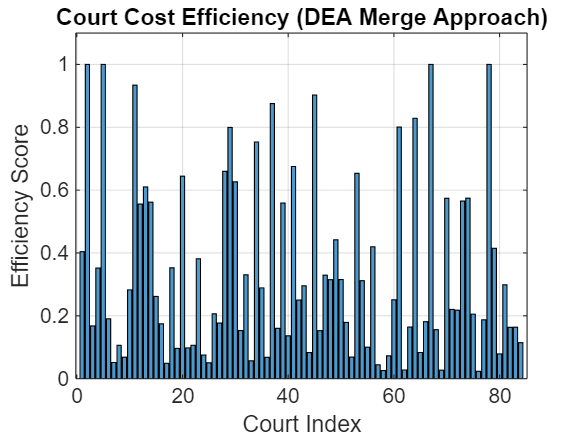

%Bar Chart of Efficiency Scores
figure;
bar(cost_efficiency_T, 'FaceColor', [0.3 0.6 0.8]);
title('Court Cost Efficiency (DEA Merge Approach)');
xlabel('Court Index');
ylabel('Efficiency Score');
ylim([0 1.1]);
grid on;

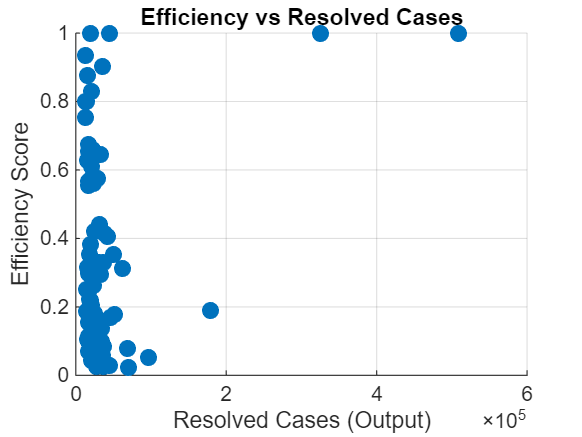

% 2. Scatter Plot: Efficiency vs Output
figure;
scatter(Y, cost_efficiency_T, 60, 'filled');
title('Efficiency vs Resolved Cases');
xlabel('Resolved Cases (Output)');
ylabel('Efficiency Score');
grid on;

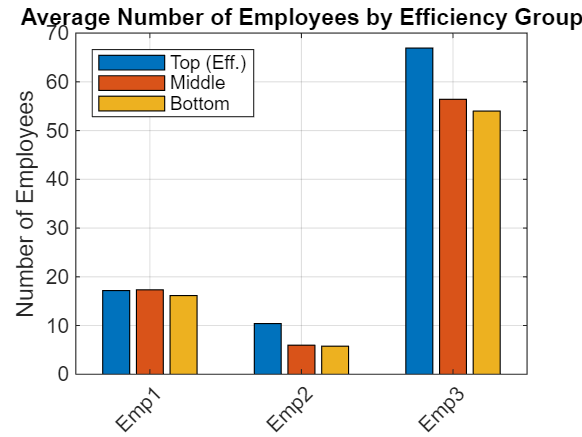

% visualisation

% Sorting all banks acc to efficiency
[~, sorted_idx] = sort(cost_efficiency_T, 'descend');
n = length(sorted_idx);
third = floor(n/3);

% indexes 3 grup
top_idx    = sorted_idx(1:third);
middle_idx = sorted_idx(third+1:2*third);
bottom_idx = sorted_idx(2*third+1:end);

% 2: means from data
emp_top    = mean(data_inout(top_idx, 1:3));
emp_mid    = mean(data_inout(middle_idx, 1:3));
emp_bottom = mean(data_inout(bottom_idx, 1:3));

wage_top    = mean(data_inout(top_idx, 4:6));
wage_mid    = mean(data_inout(middle_idx, 4:6));
wage_bottom = mean(data_inout(bottom_idx, 4:6));

asset_top    = mean(data_inout(top_idx, 10));
asset_mid    = mean(data_inout(middle_idx, 10));
asset_bottom = mean(data_inout(bottom_idx, 10));

% CHARTS

% 1. number of employees
figure;
bar([emp_top; emp_mid; emp_bottom]');
set(gca, 'XTickLabel', {'Emp1','Emp2','Emp3'}, 'XTickLabelRotation', 45);
legend({'Top (Eff.)', 'Middle', 'Bottom'}, 'Location', 'northwest');
title('Average Number of Employees by Efficiency Group');
ylabel('Number of Employees');
grid on;

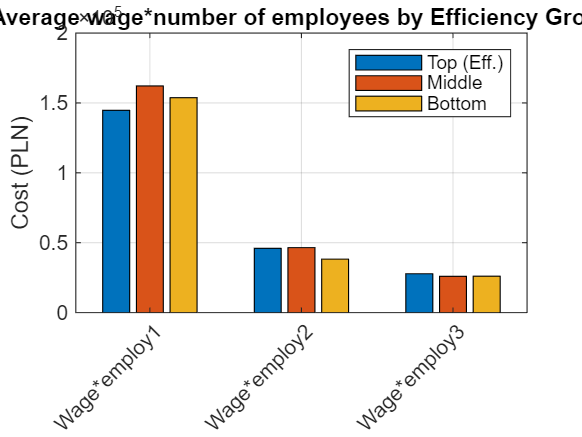


% 2. variable wages
figure;
bar([wage_top; wage_mid; wage_bottom]');
set(gca, 'XTickLabel', {'Wage*employ1','Wage*employ2','Wage*employ3'}, 'XTickLabelRotation', 45);
legend({'Top (Eff.)', 'Middle', 'Bottom'}, 'Location', 'northeast');
title('Average wage*number of employees by Efficiency Group');
ylabel('Cost (PLN)');
grid on;


% 3. Assets
figure;
bar([asset_top; asset_mid; asset_bottom]');
set(gca, 'XTickLabel', {'Asset1','Asset2','Asset3'});
legend({'Top (Eff.)', 'Middle', 'Bottom'}, 'Location', 'northeast');

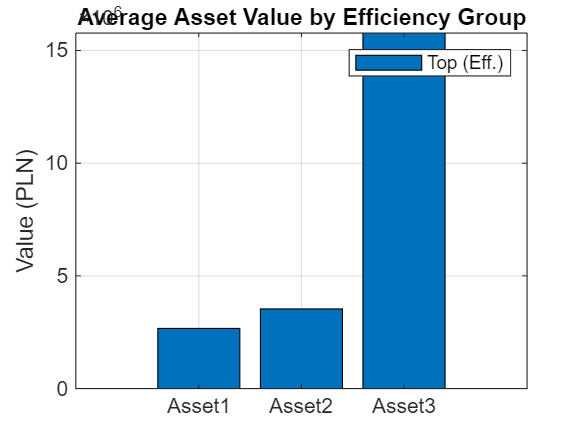

         0.404250794653733
                         1
         0.167824639380492
         0.351983679863764
                         1
         0.190422248367047
        0.0514480792429996
         0.106031773633871
        0.0683372898337221
         0.282591450716729
         0.933913594702018
         0.555702859249834
         0.610296685972838
         0.561719891153358
          0.26158408729301
         0.174412182683343
        0.0490862998506394
         0.352930227466016
        0.0962064400246729
         0.644499619276545
        0.0977947186542141
         0.106354029583019
         0.381565381537254
         0.075078326427767
        0.0503802557482559
         0.206351963542508
         0.177052335126588
         0.659747749849863
         0.799593462793818
         0.626388181136218
         0.153127859208791
          0.33066173028028
        0.0567042596671284
         0.753164298843095
         0.288939033713141
         0.067791165637079
         0.875570401802418
 

title('Average Asset Value by Efficiency Group');
ylabel('Value (PLN)');
grid on;